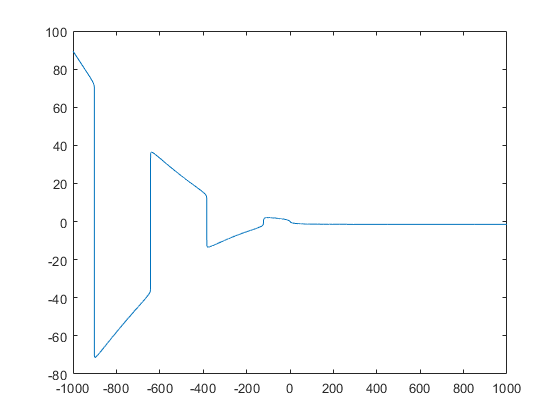

% Delta value
delta = 0.02;
Omega = solveOmega(delta, options);

gain = 50;
tau0 = 0.1;
g = 1.5;
R = 1;

% Equation functions
tauE = @(x) tau0/(R*gain) + x/R;

if delta == 0
    F = @(z) g*gain*R*cos(Omega*tau0)*(exp(-z*tau0/(R*gain))-1);
else
    int1 = @(x,z) cos(-Omega*gain*tauE(x) + x).*exp(-z*tauE(x) - x.^2/2/delta^2) / sqrt(2*pi*delta^2);
    int2 = @(x,z) -cos(-Omega*gain*tauE(x) + x).*exp(-x.^2/(2*delta^2))/sqrt(2*pi*delta^2);

    % the non-linear equation is expressed as lambda = F(lambda)
    F = @(z) g*gain*R*integral(@(x) int1(x,z), 0, Inf) + g*gain*R*integral(@(x) int2(x,z), 0, Inf);
end

x_arr = linspace(-1000, 1000, 10000);
y_arr = zeros(size(x_arr));

for i = 1:numel(x_arr)
    y_arr(i) = F(x_arr(i));
end

figure
plot(x_arr, sign(y_arr).*log10(1 + abs(y_arr)));